## Radiator requirements and operating conditions

The radiator is used to cool the cooling liquid after leaving the cold plate back to its desired cooling temperature. The air is assumed to have ambient room temperature of a maximum of 20°C. A fan is used to create the airflow. The coolant inlet temperature is entering the radiator at 30°C, which is the maximum cold plate outlet temperature and should be cooled down to 25°C. 

#### Operating conditions

QDiss           = simscape.Value(2000, "W") + simscape.Value(10, "W");  % Heat to be dissipated by radiator
deltaTCoolant   = simscape.Value(5, "deltadegC");                       % Maximum temperature rise
TCoolantIn      = simscape.Value(25, "degC");                           % Assumed coolant inlet temperature
TCoolantOutMax  = simscape.Value(30, "degC");                           % Maximum coolant outlet temperature = Raditor inlet temperature
TAmbient        = simscape.Value(20, "degC");                           % Ambient temperature
pLoop           = simscape.Value(2, "bar");                             % Pressure in coolant loop
VDotAir         = simscape.Value(0.8, "m^3/s");                         % Assumed air flow rate from fan
pAmbient        = simscape.Value(1, "atm");                             % Ambient pressure

#### Water properties at 25°C

cpCoolant       = simscape.Value(4180.74, "J/(kg*K)");      % Coolant heat cpacity
rhoCoolant      = simscape.Value(997.137, "kg/m^3");        % Coolant density
muCoolant       = simscape.Value(8.89995e-4, "Pa*s");       % Coolant dynamic Pa·s
kCoolant        = simscape.Value(0.607, "W/(m*K)");         % Coolant thermal conductivity 
PrCoolant       = simscape.Value(6.134, "1");               % Coolant Prandtl number

#### Air properties at 20°C and ambient pressure

cpAir           = simscape.Value(1006, "J/(kg*K)");         % Air heat cpacity
rhoAir          = simscape.Value(1.204, "kg/m^3");          % Air density
kinViscAir      = simscape.Value(15e-6, "m^2/s");           % Air kinematic viscosity
PrAir           = simscape.Value(0.71, "1");                % Air Prandtl number
kAir            = simscape.Value(0.026, "W/(m*K)");         % Air thermal conductivity 

#### Coolant flow rate

The flow rate used in the calculations is the nominal flow rate as determined in [ColdPlate](matlab:open('.\ColdPlate.mlx')).

mDot    = QDiss/(cpCoolant*deltaTCoolant); % Coolant mass flow rate
VDot    = mDot/rhoCoolant;                 % Coolant volumetric flow rate

#### Sizing the radiator 

We will use the following layout and parameters as a design for the radiator:

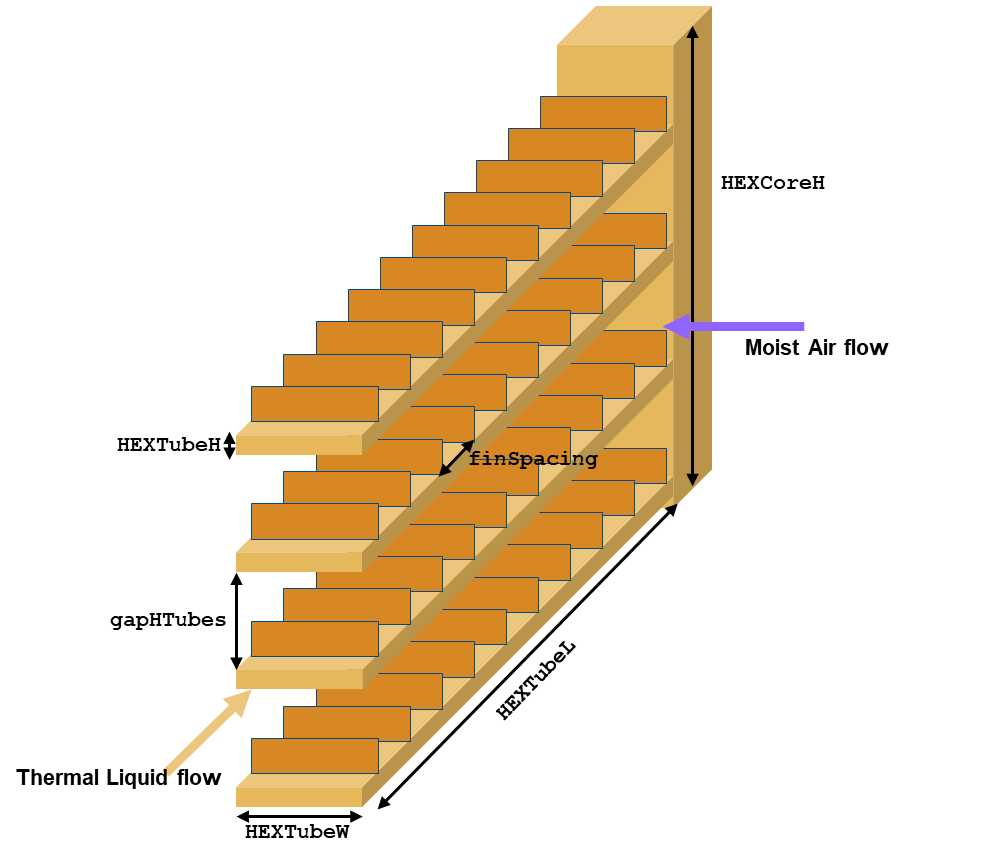

We will use the component [Heat Exchanger (TL-MA)](https://www.mathworks.com/help/releases/R2025a/hydro/ref/heatexchangertlma.html), which allows us to model a *Flow inside one or more tubes* on the Thermal Liquid (the coolant) side. We can use the *Generic *model on the Moist Air (the ambient air) side. For the setup we calculate some derived geometric parameters needed. Additional derived parameters include wall thermal resistance and wall thermal mass. 

HEXCoreL        = simscape.Value(400, "mm");        
HEXCoreH        = simscape.Value(400, "mm");     
HEXCoreW        = simscape.Value(88, "mm");         
HEXTubeW        = simscape.Value(88, "mm");         
HEXTubeH        = simscape.Value(3, "mm");          
HEXTubeL        = simscape.Value(400, "mm");
HEXTubeD        = simscape.Value(1, "mm");
numTubes        = 16;
tubeRoughness   = simscape.Value(15e-6, "m");
finEfficiency   = 0.75;                        
finSpacing      = simscape.Value(2, "mm");
tubeK           = simscape.Value(167, "W/(m*K)");
tubeRho         = simscape.Value(2700, "kg/m^3");
tubeCp          = simscape.Value(880, "J/(kg*K)");


HEXTubeWOuter = HEXTubeW+2*HEXTubeD;                                        % Heat exchanger tube outer width
HEXTubeHOuter = HEXTubeH+2*HEXTubeD;                                        % Heat exchanger tube outer height

tubesCrossArea = HEXTubeW*HEXTubeH;                                         % Heat exchanger tube cross-sectional area

areaOuterTubes = numTubes*2*(HEXTubeWOuter+HEXTubeHOuter)*HEXTubeL;         % Surface area of all tubes
areaInnerTubes = numTubes*2*(HEXTubeW+HEXTubeH)*HEXTubeL;                   % Inner area of tubes for heat transfer

tubesDh= 2*HEXTubeW*HEXTubeH/(HEXTubeW+HEXTubeH);                           % Hydraulic diameter tubes

gapHTubes = (HEXCoreH - numTubes*HEXTubeH)/(numTubes - 1);                  % Gap between tubes
areaAirFlow = (numTubes - 1)*HEXTubeL*gapHTubes;                            % Flow area on air side
airDh = 4*areaAirFlow/((numTubes-1)*2*(HEXTubeL+gapHTubes));                % Hydraulic diameter air side
numFins = (numTubes-1)*HEXCoreH/finSpacing;                                 % Number of fins

areaAirFins = 2*numFins*HEXTubeW*gapHTubes;                                 % Surface area of fins

areaResistance = numTubes*areaOuterTubes;                                   % Surface area of tubes used to calculat wall thermal resistance
HEXThermalResistance = HEXTubeD/tubeK/areaResistance;                       % Tube wall thermal resistance                                 
volumeTubes = (HEXTubeWOuter*HEXTubeHOuter-HEXTubeW*HEXTubeH)*HEXTubeL;     % Volume per tube
HEXWallMass = numTubes*tubeRho*volumeTubes;                                 % Combined tube mass


For the Moist Air side in the heat exchanger block, the flow geometry will be set to *Generic *in this case the model uses the Colburn equation to calculate the Nusselt number. The select coefficients, we calculate the Reynolds number at nominal operating conditions. On the air side we will add a Flow Resistance MA to account for a small additional pressure loss associated with the air intake. 

Re = VDotAir*airDh/(kinViscAir*areaAirFlow);                                % Reynolds on air side at nominal conditions
HEXColburnCoefficients = [0.211, .651, .273];                               % Literature Colburn equation coefficients for Reynolds number at nominal operating conditions

dpNominalAir = simscape.Value(5e-4, "MPa");  

We will test this in a Simscape model. 

open_system("example_Radiator")

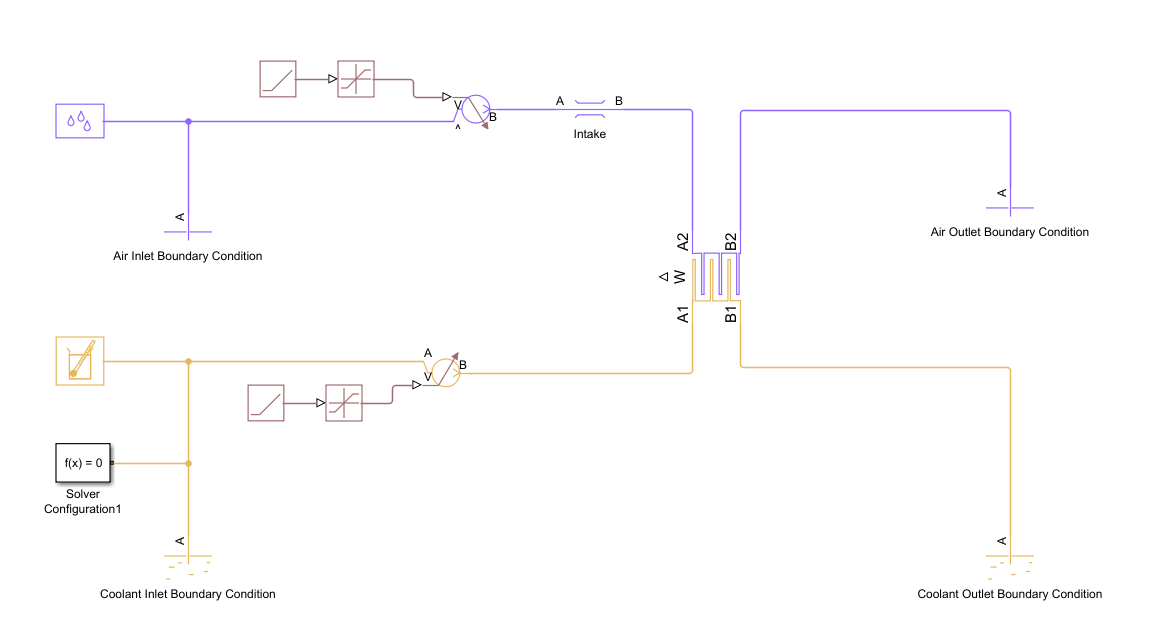

The model is setup with the above parameters. The Moist Air Side has the *Flow Geometry* set to *Generic*, 

On the Thermal Liquid side the model is initialized at the assumed loop pressure and the cold plate outlet temperature. On the air side the model is initialized at ambient pressure and temperature. As in previous models we set the cross-sectional areas of connected ports to similar values. On the Thermal Liquid side, this is the tube cross-sectional area. On the air side the flow area in the radiator. 

The parameter "Wall thermal mass" is also enabled, for danymic simulation this adds a capacitance to the component, making it more robust during fluctuations in dynamic simulations. 

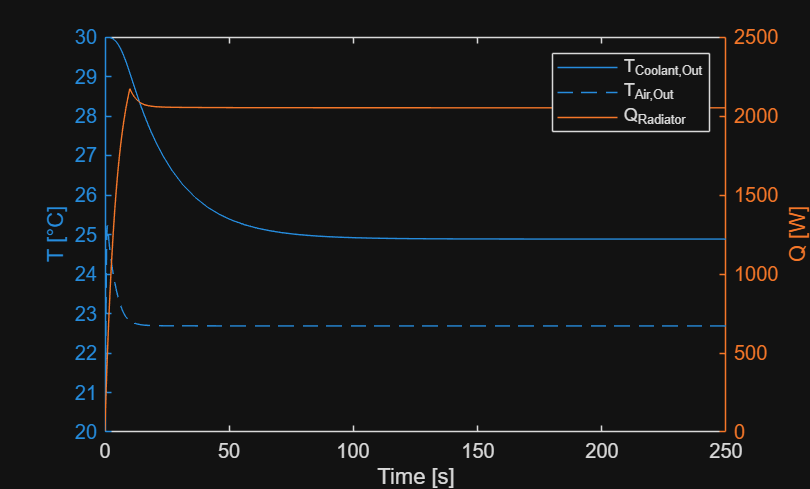

simInp = Simulink.SimulationInput("example_Radiator");
simInp = simInp.setModelParameter("StopTime","250");

simOut = sim(simInp);

TCoolantRadiatorOut = simOut.simlog.Heat_Exchanger_TL_MA.B1.T.series.values("degC");
TAirRadiatorOut     = simOut.simlog.Heat_Exchanger_TL_MA.B2.T.series.values("degC");
QRadiator           = simOut.simlog.Heat_Exchanger_TL_MA.Q2.series.values("W");
figure
yyaxis left
plot(simOut.tout,[TCoolantRadiatorOut,TAirRadiatorOut])
ylabel("T [°C]")
yyaxis right
plot(simOut.tout,QRadiator)
ylabel("Q [W]")
xlabel("Time [s]")
legend("T_{Coolant,Out}","T_{Air,Out}","Q_{Radiator}")

#### Determine the coolant side radiator pressure drop

Similar to the Pipe (TL) block the pressure drop for the Thermal Liquid side, when the Pressure loss model is set to Correlations for flow inside tubes is determined using a Haaland approximation to calculate the Darcy friction factor. 

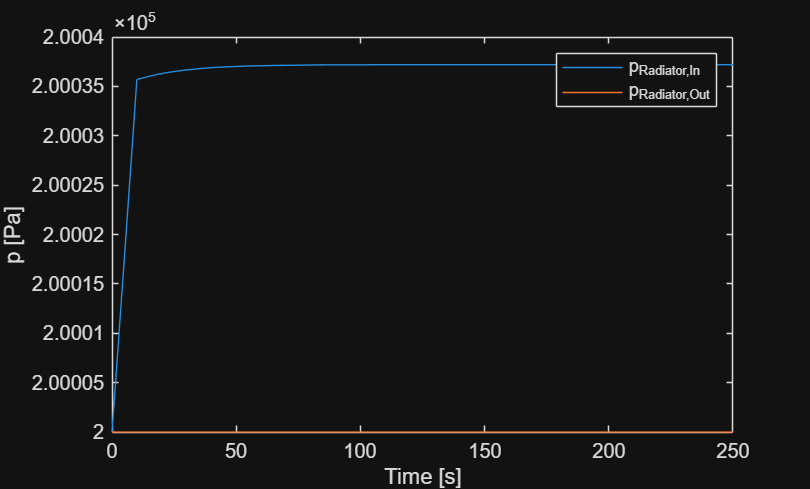

open_system("example_Radiator")

simInp = Simulink.SimulationInput("example_Radiator");
simInp = simInp.setModelParameter("StopTime","250");

simOut = sim(simInp);

pCoolantRadiatorIn  = simOut.simlog.Heat_Exchanger_TL_MA.A1.p.series.values("Pa");
pCoolantRadiatorOut = simOut.simlog.Heat_Exchanger_TL_MA.B1.p.series.values("Pa");

dpRadiator = pCoolantRadiatorIn-pCoolantRadiatorOut;


figure
plot(simOut.tout,[pCoolantRadiatorIn,pCoolantRadiatorOut])
ylabel("p [Pa]")
xlabel("Time [s]")
legend("p_{Radiator,In}","p_{Radiator,Out}")
hold off


disp(dpRadiator(end))

   37.2057



At steady state for the maximum flow rate, the current cold plate design produces a pressure drop of roughly 12 Pa which is as expected  small compared to what is caused by the cold plate and all additional piping. 

The air side pressure loss at nominal conditions is:

pFanIn  = simOut.simlog.Intake.A.p.series.values("Pa");
pFanOut = simOut.simlog.Heat_Exchanger_TL_MA.B2.p.series.values("Pa");
dpFan = pFanIn-pFanOut;

disp(dpFan(end))

  696.6131



#### Fan parameterization

A fan will be used on the Moist Air side to create a forced air flow through the radiator. To model that component, we will use the Fan (MA) block. For the determined pressure loss at nominal conditions, we will select a suitable fan from a vendor. According to the following curve the pressure rise at given flow rates should be achievable. The curve shows the pressure flow rate relation ship for at  different fan speeds, tand additionally the pump break power is given. 

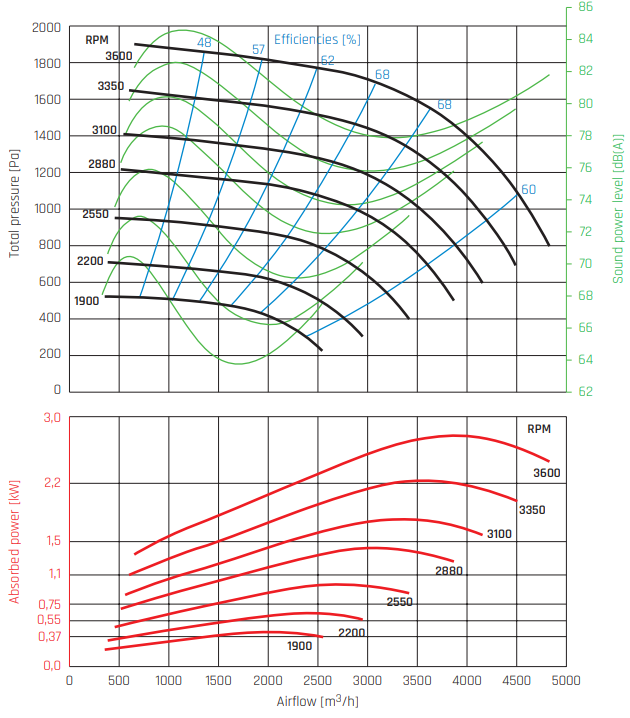

Again, we can use the [Graph Data Extractor](https://www.mathworks.com/help/releases/R2025b/simscape/ref/graphdataextractor.html) to extract the lookup tables needed to parameterize the Simscape component. See the script [createFanData](matlab:open('..\Docs\createFanData.m')) how the data from the Graph Data Extractor is processed. 

load("fanData.mat")

Testing the fan in a Simscape model. 

open_system("example_Fan")

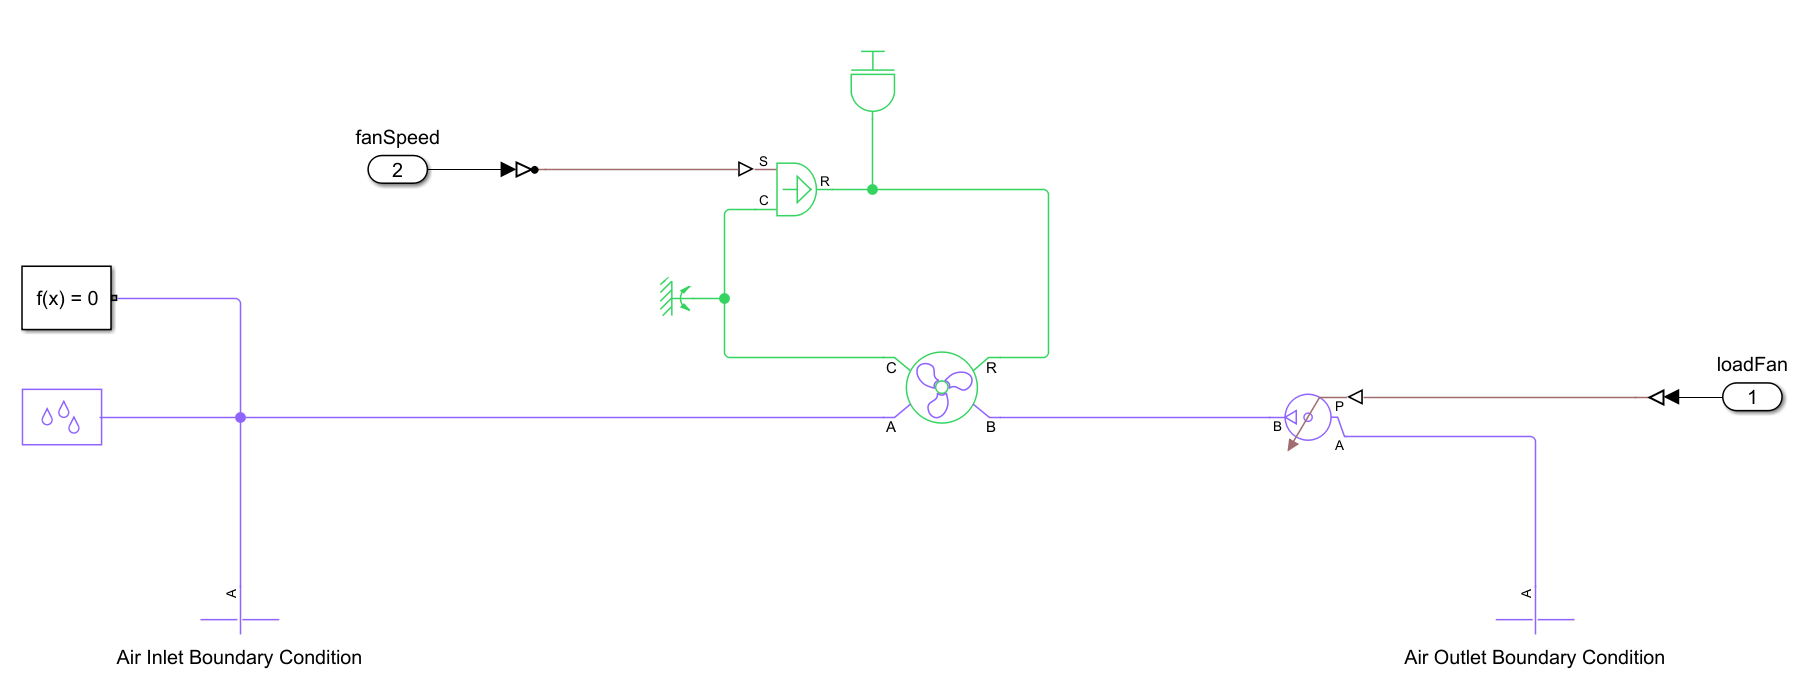

With the data provided, we can select the *Fan parameterization* method *2-D Tabulated Data Parameterization - Pressure as a Function of Shaft Speed and Flow Rate *and the *Shaft power specification* to *Brake power*. As with the pump, you can also validate the fan curve with the current paramterization by right-clicking the fan component and selecting *Fluids->Plot Fan Characteristics:*

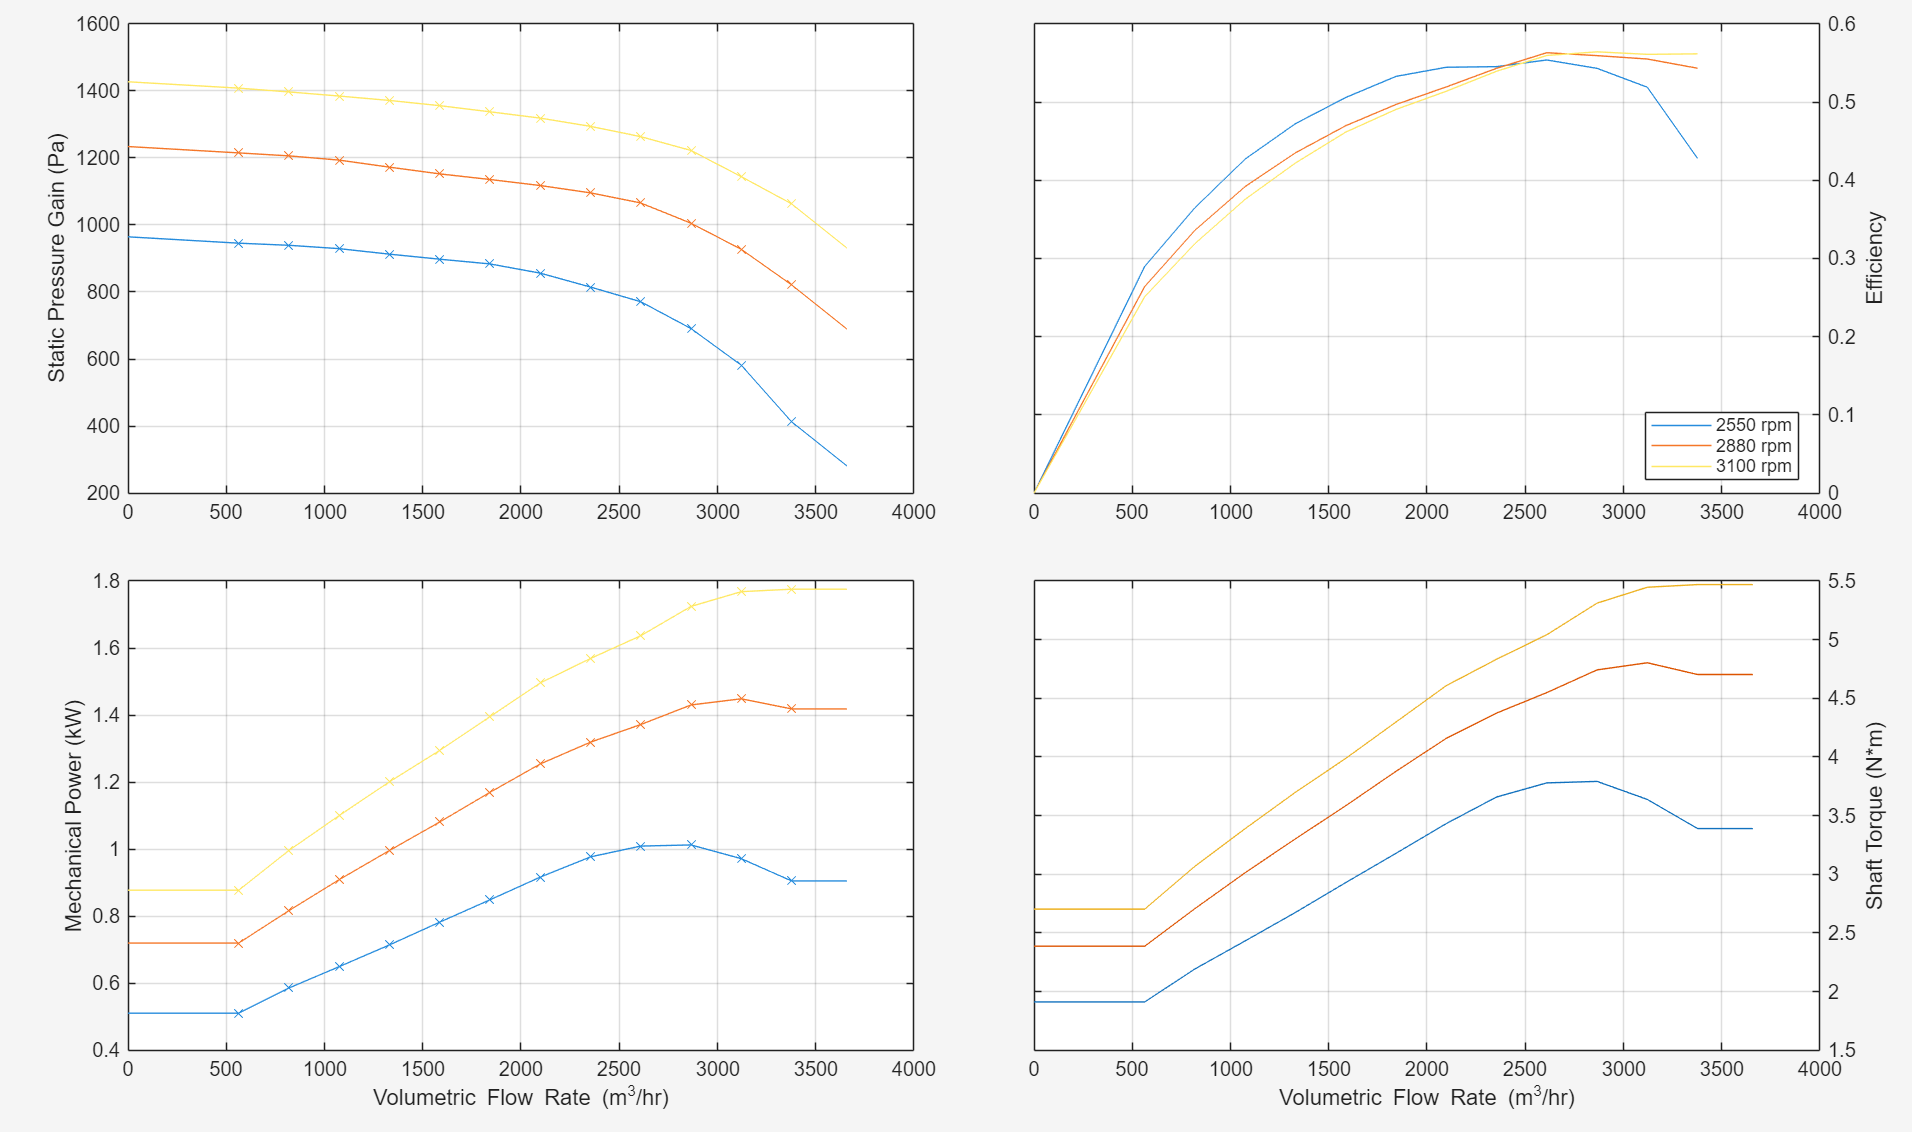

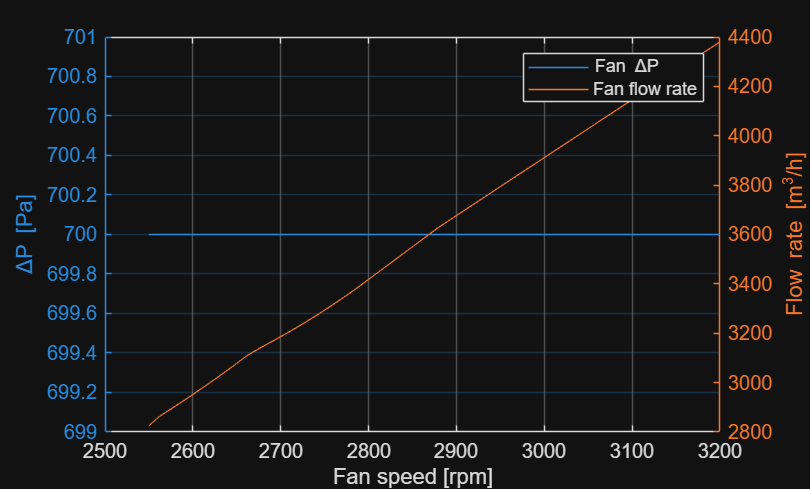


dpReq          = simscape.Value(700, "Pa");          
tInFanTest     = [0;10;60];
loadInFanTest  = [dpReq.value("Pa");dpReq.value("Pa");dpReq.value("Pa")]; % Pressure load used for testing 
speedInFanTest = [2550;2550;3200];                                        % Fan speed used for testing 
fanRefInit     = simscape.Value(speedInFanTest(1),"rpm"); 


simInp = Simulink.SimulationInput("example_Fan");
simInp = simInp.setModelParameter("StopTime","60");
simInp = simInp.setExternalInput([tInFanTest,loadInFanTest,speedInFanTest]);

fanRefSpeed     = simscape.Value(2550, "rpm");
fanInertia      = simscape.Value(0.01, "kg*m^2");

simOut = sim(simInp);

pLoad       = simOut.simlog.Pressure_Source_MA.P.series.values("Pa");
VDotFan     = simOut.simlog.Fan_MA.q_A.series.values("m^3/hr");
speedFan    = simOut.simlog.Fan_MA.omega.series.values("rpm");
effFan      = simOut.simlog.Fan_MA.efficiency.series.values("1");

figure
yyaxis left
plot(speedFan,pLoad);
ylabel("\DeltaP [Pa]")
yyaxis right
plot(speedFan,VDotFan);
ylabel("Flow rate [m^3/h]")
xlabel("Fan speed [rpm]")
grid on
legend("Fan \DeltaP","Fan flow rate")
hold off

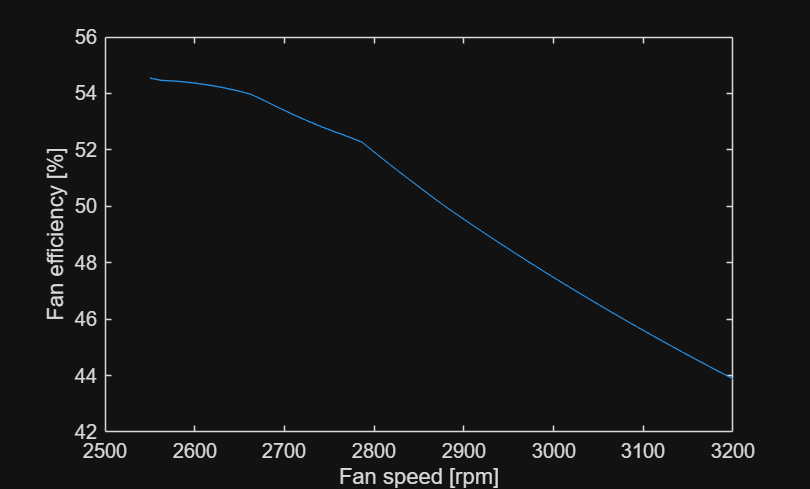

figure
plot(speedFan,effFan*100);
ylabel("Fan efficiency [%]")
xlabel("Fan speed [rpm]")

In the speed range tested for the given statc pressure rise, the fan created between roughly 2000 and 4000 m^3/h, we assumed an operating condition of 0.8 m^3/s = 2880 m^3/h. 

From the plot we can see, that this related to roughly 2600 rpm.

fanSpeed  = simscape.Value(2600, "rpm");